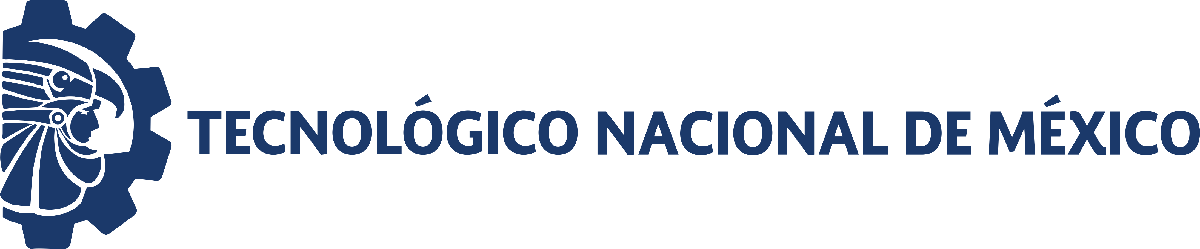                                 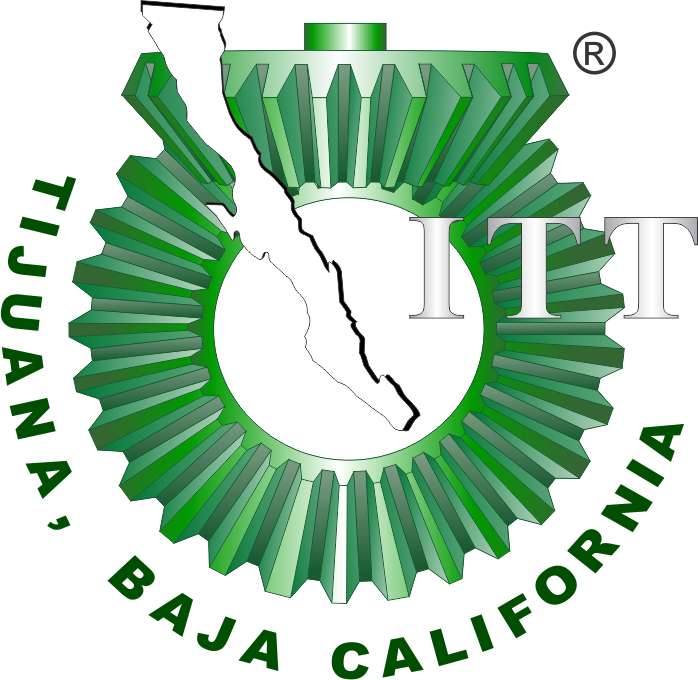

# Práctica 3: Sistema musculoesquéletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

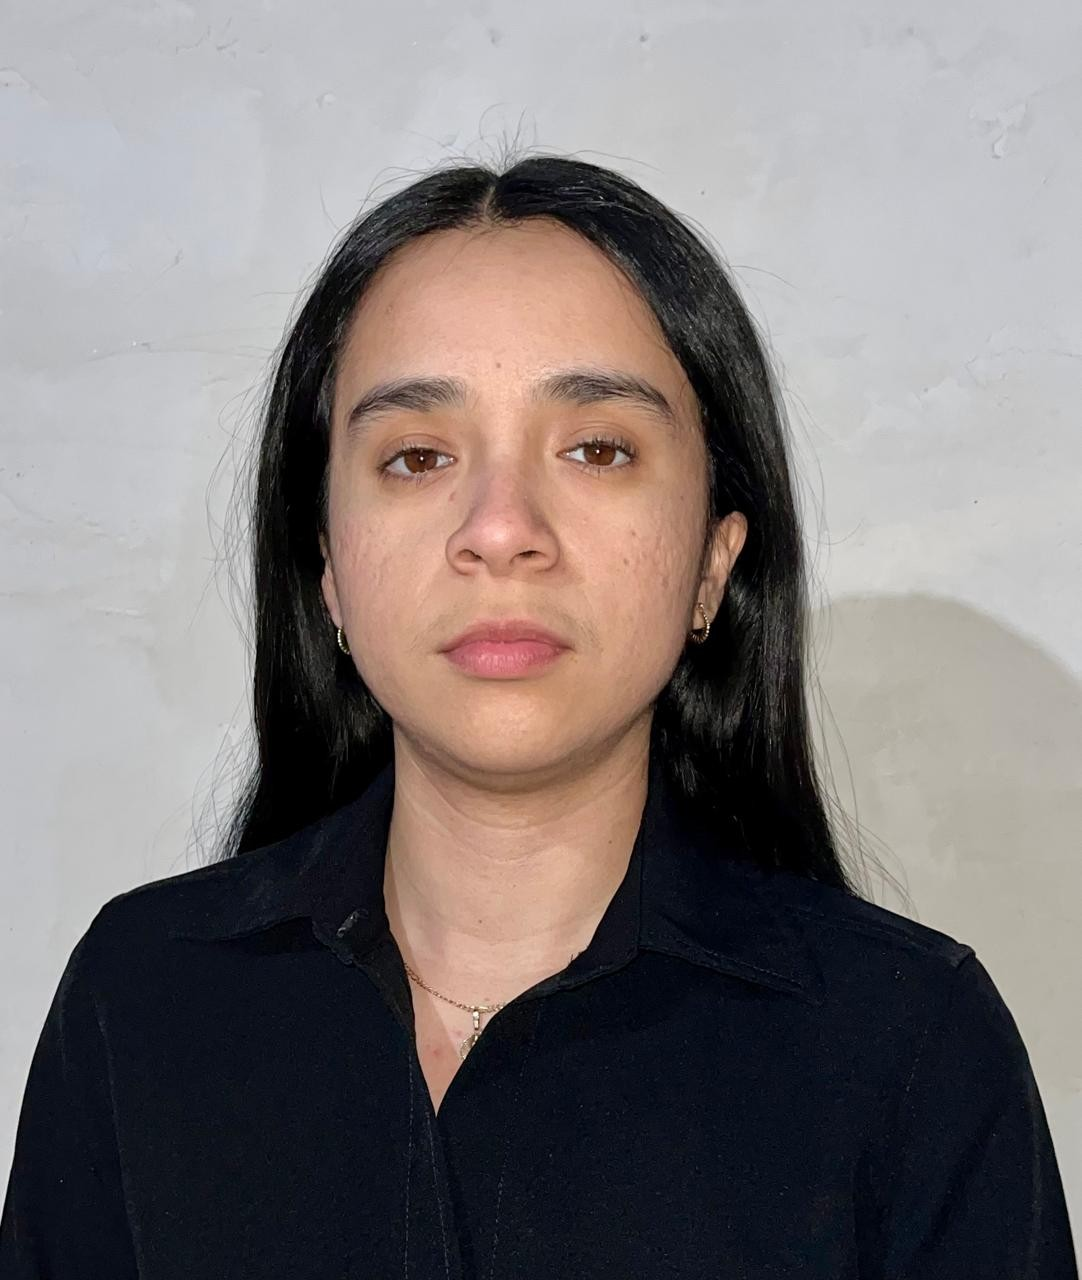

Nombre del alumno: **Adriana Estefania Bañuelos Ocampo**

Número de control: **23210694**

Correo institucional: **L23210694@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file= 'Sistema';
open_system(file);
parameters.StopTime='15';
parameters.Solver='ode15s';
parameters.MaxStep='1E-3';
x=sim(file,parameters);


## Respuesta del sistema

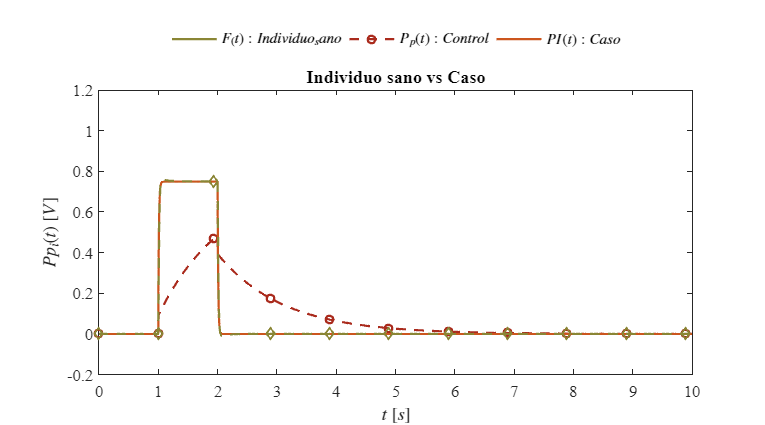

plotsignals(x.t,x.Pp1,x.Pp2,x.Pp3,x.PI)

## Función: Respuestas a las señales 

function plotsignals(t,Pp1,Pp2,Pp3,PI)
    figure('Color','w')
    set(gcf,'Units','centimeters','Position',[1,1,18,10])

     colors = [138, 134, 53;
              170, 43, 29;
              204, 86, 30]/255;
    colororder(colors)

    plot(t,Pp1,'-',t,Pp2,'--o',t,Pp3,t,PI,'--d',...
        'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L = legend('$F_(t):Individuo_sano$','$P_p(t):Control$','$PI(t):Caso$');
    set(L,'Interpreter','latex','FontSize',10,'Location','northoutside','Box','off','Orientation','horizontal')
    xlabel('$t$ $[s]$','Interpreter','latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','latex','FontSize',11)
    xlim([0,10]); xticks(0:1:10)
    ylim([-0.2,1.2]); yticks(-0.2:0.2:1.2)
    title('Individuo sano vs Caso','FontSize',10)
    set(gca,'FontName','Times New Roman','FontSize',11)

   
    exportgraphics(gcf,'Sistemamusculoesqueletico.pdf','ContentType','vector')
end